# 单输出高斯过程回归

准备工作：

clear,clc,close all

rng(0);
% 训练前准备工作
nTrain = 10; %训练点的个数
nTest = 50; %测试点的个数
noSamples = 10; % no of samples to be plotted
trData = trainData(nTrain); % 训练数据
disp('训练数据结构')

训练数据结构


disp(trData)

    n: 10
    x: [10×1 double]
    y: [10×1 double]
    K: [10×10 double]
    L: [10×10 double]



teData = testData(nTest); % 测试数据
disp('测试数据结构')

测试数据结构


disp(teData)

    n: 50
    x: [50×1 double]
    y: [50×1 double]




$$y_{obs}=y_{true}+w,w \sim N(0,\sigma^2)$$


给定超参数后直接推断结果：

t_estData = MeanVarEst(trData,teData); % compute the mean and variance of test data
disp('预测数据结构')

预测数据结构


disp(t_estData)

     mu: [50×1 double]
    sig: [50×1 double]
    Lpr: [50×50 double]
    Lpo: [50×50 double]



结果：

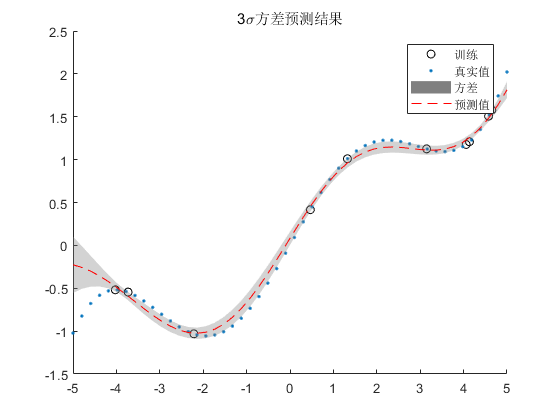

figure(1)
hold on
plot(trData.x, trData.y, 'ok');
plot(teData.x, teData.y, '.');%这里的y是真实值，用于对比
xpl = [teData.x', fliplr(teData.x')];
ypl = [(t_estData.mu-3*t_estData.sig)', fliplr((t_estData.mu+3*t_estData.sig)')];
fill(xpl,ypl,[0.5,0.5,0.5],'facealpha',0.35,'EdgeColor','None');
plot(teData.x, t_estData.mu, 'r--'); %预测值
legend('训练','真实值','方差','预测值');
title('3\sigma方差预测结果')

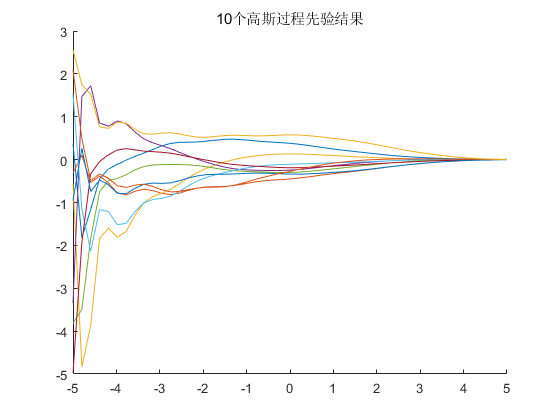


fPrior =  t_estData.Lpr*randn(teData.n,noSamples); %draw 10 samples out of the prior distribution
figure(2);
hold on;
plot(teData.x, fPrior);
title('10个高斯过程先验结果');

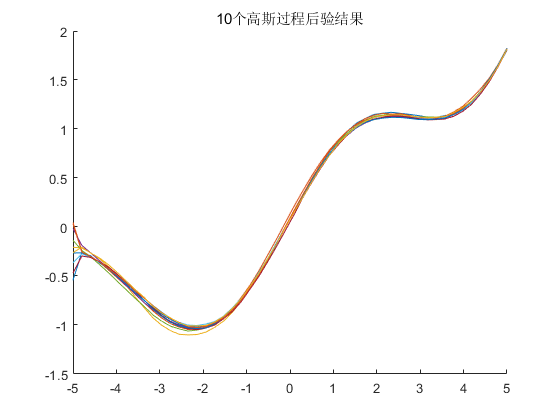


fPost = repmat(t_estData.mu,1,noSamples) + t_estData.Lpo*randn(teData.n,noSamples);
figure(3);
hold on;
plot(teData.x, fPost);
title('10个高斯过程后验结果');

对超参数进行优化：


$$$$L\left( \Theta  \right) =  - \frac{N}{2}\log \left( {2\pi } \right) - \frac{1}{2}\log \left| {K\left( {X,X} \right) + \sigma _n^2} \right| - \frac{1}{2}{y^T}{\left( {K\left( {X,X} \right) + \sigma _n^2} \right)^{ - 1}}y$$$$



$$$$\hat \Theta  = \arg \min \left( { - L\left( \Theta  \right)} \right)$$$$



$$$$\frac{{\partial L\left( \Theta  \right)}}{{\partial {\Theta _j}}} = \frac{1}{2}tr\left( {\left( {{K^{ - 1}}y} \right){{\left( {{K^{ - 1}}y} \right)}^T}\frac{{\partial K}}{{\partial {\Theta _j}}}} \right)$$$$


# 相关函数：

function y = trueFunction(x)
    y = sin(0.9*x) + 0.02*(x.^2) + 0.02*(x.^3);
    %y = 0.67*x.^2);
    %y = sin(0.6*x)
end

function trData = trainData(nTrain)
    s = 0.0005; %高斯分布的观测噪声
    trData.n = nTrain;
    trData.x = sort((10)*rand(nTrain,1) - 5); %[-5 5]的nTrain个随机数
    trData.y = trueFunction(trData.x) + s*randn(nTrain,1); %测量值
    para0 = [1 0.0005 0.1];
    %%%含噪声GP
    trData.K = Kernel(trData.x,trData.x,para0) + para0(2).*eye(nTrain); % 计算训练数据的核函数
    %%%不含噪声GP
    % trData.K = Kernel(trData.x,trData.x,para0);
    trData.L = chol(trData.K + 1e-6*eye(trData.n)); %cholesky分解（避免求逆运算）
end

function teData = testData(nTest)
    teData.n = nTest;
    teData.x = linspace(-5, 5, nTest)';
    teData.y = trueFunction(teData.x);
end

核函数，超参数传递进去


$$$k(x,x') = \sigma _f^2\exp \left( { - \frac{1}{2}\sum\limits_i^d {{{\left( {\frac{{{r_i}}}{{{l_i}}}} \right)}^2}} } \right) + \sigma _n^2{\delta _{pq}},{r_i} = {x_{pi}} - {x_{qi}}$$$


function K = Kernel(x1,x2,para)
    K = zeros(size(x1,1),size(x2,1));
    param1 = para(1); %可调超参数1
    param2 = para(3); % 可调超参数2，this controls the width of the kernel. Large values makes the fit a straight line
    for i = 1:size(x1,1)
    	for j = 1:size(x2,1)
    	   K(i,j) = param1*exp(-0.5*param2*(x1(i)-x2(j))^2);
    	end
    end
end

函数MeanVarEst中：

Ks即$ K({X_*},X)$

Kss即$ K({X_*},{X_*})$

trData.K即$K(X,X) + \sigma _n^2I$


$$$${\bar f_*} = K({X_*},X){[K(X,X) + \sigma _n^2I]^{ - 1}}y$$$$



$$$${\mathop{\rm cov}} ({f_*}) = K({X_*},{X_*}) - K({X_*},X){[K(X,X) + \sigma _n^2I]^{ - 1}}K(X,{X_*})$$$$


function t_estData = MeanVarEst(trData,teData)
    para_bst = [1 0.0005 0.1];
    Ks = Kernel(trData.x, teData.x,para_bst); %Kstar
    Kss = Kernel(teData.x, teData.x,para_bst); %Kstar_star
    t_estData.mu = Ks'*(trData.K\trData.y); %均值
    t_estData.sig = sqrt((diag(Kss - Ks'*(trData.K\Ks)))); %方差，协方差矩阵的主对角元素
    t_estData.Lpr = chol(Kss + 1e-6*eye(teData.n)); %先验的cholesky分解
    t_estData.Lpo = chol(Kss - Ks'*(trData.K\Ks) + 1e-5*eye(teData.n)); %后验的cholesky分解
end
function [diffs,target] = OptimTargetDiff(paras,trData,teData)
    s = trData.K;
    target = -0.5*log(det(s)) -0.5*y'*inv(s)*y -trData.n /2*log(pi);
    s = trData.K-paras(2).*eye(trData.n);
    diffs = zeros(trData.n,1);
    x1 = trData.x;
    x2 = trData.x;
    dl1=zeros(length(x1),length(x2));
    dl2=zeros(length(x1),length(x2));
    dl3=zeros(length(x1),length(x2));
    for i = 1:size(x1,1)
    	for j = 1:size(x2,1)
    	    dl1(i,j) = 2*paras(1)*exp(-0.5*((x1(i)-x2(j))/paras(3))^2);
            dl2(i,j) = 2*paras(2)*delta(i,j);
            dl3(i,j) = paras(2)^2*exp(-0.5*((x1(i)-x2(j))/paras(3))^2)*((x1(i)-x2(j))^2)/((paras(3))^3);
    	end
    end
    dl = {dl1,dl2,dl3};
    for i = 1:length(paras)
        l = dl{i}
        diffs(i) = 0.5*trace((inv(s)*y)*(inv(s)*y)'*l);
    end
end
function out = delta(i,j)
    if i==j
        out = 1;
    else
        out = 0;
    end
end